# Tank level behaviour

This livescript is a brief manual in support of the app ***tanklevelbehaviour.mlapp***.   This is a simple interface to understand the modelling and behaviour of simple tank level models, subject to changes in the core parameters such as tank volume, flow rate,  disturbances to the inlet flow and blockages in the outlet pipe. These notes give the engineering and analytical background alongside some simple MATLAB code snippets than can be used for equivalent analysis.

See website for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/mainindex](https://sites.google.com/sheffield.ac.uk/controleducation/mainindex)

A group of similar files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

A logical next file is ***tanklevel_and_pi***.***mlapp*** which looks at how to control the tank concentration using a PI compensator.

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Context of the tank system

- Open-loop step response analysis

- Using the app to validate expectations

- Supporting MATLAB code

-  Interface and user interaction of the app file

## 1. Context of the tank level system 

The figure below shows the maximum extent of the tank dimensions, so a width of upto 10 and a depth of 9. 

- The width/area can be modified by the user. 

- The water exits the tank from the outlet in the bottom right which has variable dimensions (linked to a conductance term *R*), again adjustable by the user. 

- The red rectangle represents a plug or bung which, from time to time moves down and acts as a blockage on the outlet pipe thus reducing its area and thus the corresponding outflow. The user can also vary the percentage overlap of this bung with the outlet.

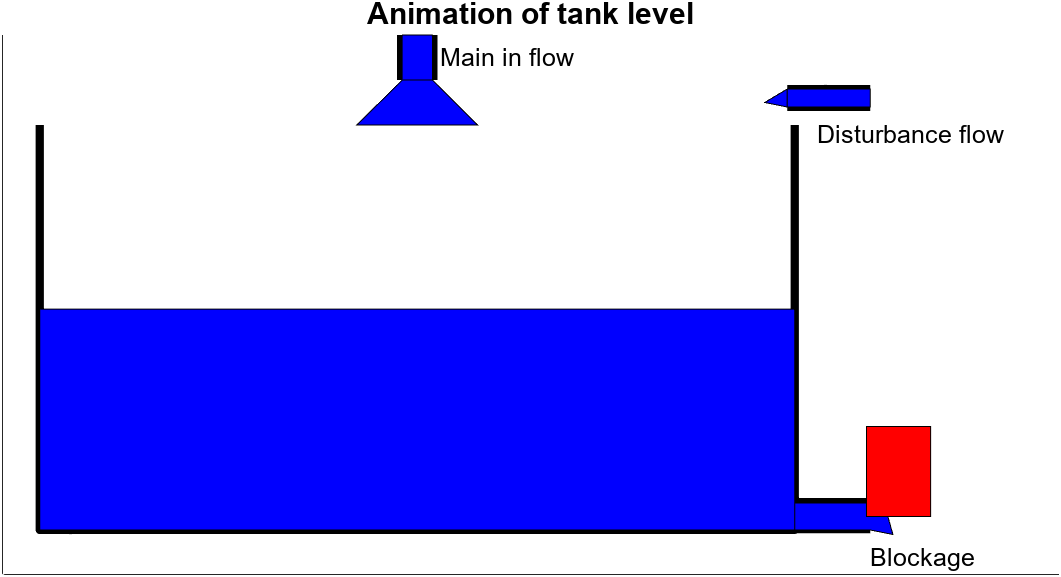

There are two input flows:

- the flow in the top centre is a controllable flow which the user adjusts to achieve the desired depth. This flow could be selected via open-loop or closed-loop mechanisms.

- the flow on the top right is a disturbance flow which again can be varied by the user. 

### Model of the tank system

Assume cross-sectional area *A* and that the flow out is dependent on the depth *h* through a conductance parameter *R*. Then, using a volume balance the equation for the depth is governed by;


$$A\frac{\textrm{dh}}{\textrm{dt}}+\textrm{Rh}=f_{\textrm{in}} ;\;\;\;\;f_{\textrm{in}} =f+d$$


where the flow in comprises the two components: *f* for controllable flow and *d* for disturbance flow. Blockage of the outlet pipe reduces the value of parameter *R*.

## 2. Open-loop behaviour analysis

A simple model for the tank behaviour is derived using the time constant form below (assuming constant in flows). 


$$\frac{A}{R}\frac{\textrm{dh}}{\textrm{dt}}+h=\frac{1}{R}\left(f+d\right),\;\;\;\;T=\frac{A}{R},\;\;\textrm{Gain}=\frac{1}{R}$$



$$h\left(t\right)=$$

$$\frac{1}{R}\left(f+d\right)-$$

$$\left(h\left(0\right)-\frac{1}{R}\left(f+d\right)\right)$$

$$e^{-\frac{t}{T}}$$


The blockage is assumed to have a direct percentage change on the value *R*. Thus

$R\to R\left(1-B\right)$where ***B*** is the percentage/fractional blockage.

### 2.1 Impact of changes in in-flow

The in-flow* f* effects the steady-state values, so:


$$\lim_{t\to \infty } h\left(t\right)=\frac{1}{R}\left(f+d\right)$$


Thus, ignoring the disturbance term for now, the core relationship is: $h_{\textrm{ss}} =\frac{f}{R}$

### 2.2 Impact of changes in area

The area affects the time constant through the relationship: $T=\frac{A}{R},$

As area increases, the time constant becomes slower.

### 2.3 Impact of changes in disturbance flow

The disturbance flow is similar to the in-flow in how it impacts on behaviour. So a change in disturbance flow leads to a change in the steady-state depth as follows: $\delta h_{\textrm{ss}} =\frac{d}{R}$

### 2.4 Impact of changes in the blockage

As the blockage impacts on the conductance term R, it impacts on both the steady-state and the time constant.


$$T=\frac{A}{R\left(1-B\right)},\;\;\textrm{Gain}=\frac{1}{R\left(1-B\right)}$$


Hence an increase in the blockage causes an increase in the steady-state and an increase in the time constant.

## 3. Using the app to validate expectations

From a unit step response, the steady-state value will be the gain and we get 63% movement after T seconds, hence both these values can be determined quickly.

## 4. Supporting MATLAB code

For simplicity one can use Laplace transforms and step.m to form the generic open-loop model and the corresponding step response.


$$A\frac{\textrm{dh}}{\textrm{dt}}+\textrm{Rh}=f_{\textrm{in}}$$


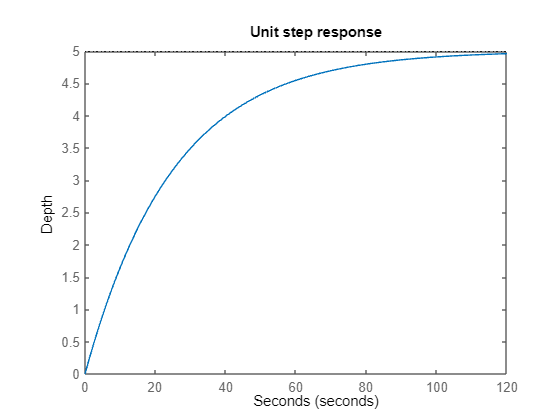

A = 5; R=0.2;
G = tf(1,[A,R]);
step(G,120)
title('Unit step response')
xlabel('Seconds')
ylabel('Depth')

### **4.1 Changes in the magnitude of the in-flow**

The function step.m assumes that f=1. Collecting and plotting the outputs separately allows for different magnitudes of f.

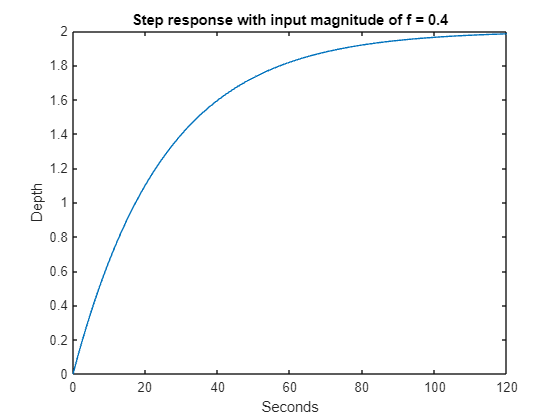

A = 5; R=0.2; f=0.4;
G = tf(1,[A,R]);
[y,t]=step(G,120);
plot(t,y*f)
title(['Step response with input magnitude of f = ',num2str(f)])
xlabel('Seconds')
ylabel('Depth')

### **4.2 Changes in the disturbance flow**

The function ***step.m*** can be used to determine the response for d=1. One can then scale to find the response for different values and use superposition to see the impact alongside the main in-flow. 

It will be clear that adding a disturbance flow, perhaps unsurprisingly, increases the steady-state.

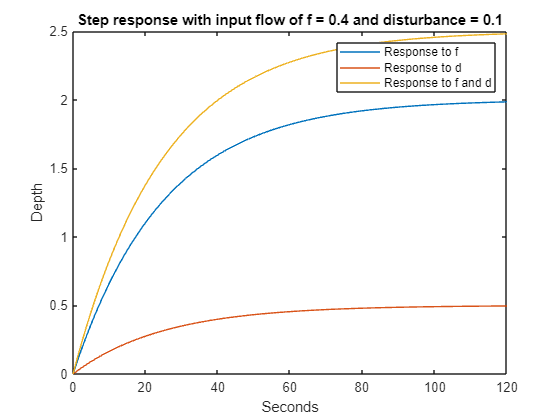

A = 5; R=0.2; f=0.4; d=0.1;
G = tf(1,[A,R]);
[y,t]=step(G,120);
plot(t,y*f,t,y*d,t,y*(d+f))
title(['Step response with input flow = ',num2str(f),' and disturbance = ',num2str(d)])
legend('Response to f','Response to d','Response to f and d')
xlabel('Seconds')
ylabel('Depth')

### **4.3 Impact of changes in area**

One can overlay the responses with different areas by producing a number of different models and the associated behaviours.

 It will be clear here that the time constant changes (increases as *A* increases) but the steady-state is the same.

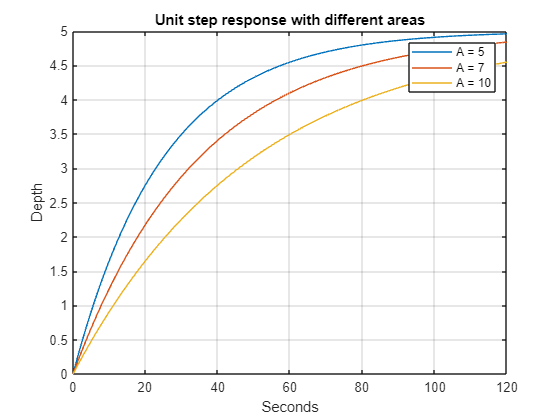

A1 = 5; A2 = 7; A3 =10;
R=0.2; f=0.4;
G1 = tf(1,[A1,R]);
G2 = tf(1,[A2,R]);
G3 = tf(1,[A3,R]);
[y1,t]=step(G1,120);
[y2]=step(G2,t);
[y3]=step(G3,t);
plot(t,y1,t,y2,t,y3);grid
title(['Unit step response with different areas'])
legend(['A = ' num2str(A1)],['A = ' num2str(A2)],['A = ' num2str(A3)])
xlabel('Seconds')
ylabel('Depth')

### **4.4 Impact of blockages**

This is easiest illustrated by having multople models to represent different blockages.

It is clear from the plots that as the blockage grows the time constant gets slower and the steady-state increases.

A = 5; 
B1=0; B2=0.20; B3 = 0.50;

B1 = 0

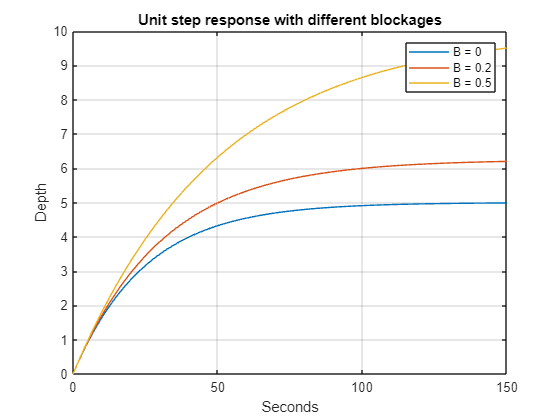

R=0.2; f=0.4;
G1 = tf(1,[A,R*(1-B1)]);
G2 = tf(1,[A,R*(1-B2)]);
G3 = tf(1,[A,R*(1-B3)]);
[y1,t]=step(G1,150);
[y2]=step(G2,t);
[y3]=step(G3,t);
plot(t,y1,t,y2,t,y3);grid
title(['Unit step response with different blockages'])
legend(['B = ' num2str(B1)],['B = ' num2str(B2)],['B = ' num2str(B3)])
xlabel('Seconds')
ylabel('Depth')

## **5. **Interface and user interaction of the app file

The user can change 5 parameters (Area, conductance, flow-in, disturbance flow and blockage percentage) and thus investigage easily the impact of changes. The parameters can only take a finite number of discrete values, as on the sliders, to avoid excessive decimal places.

- The top figure shows the tank and inlet/outlet pipes. The dimensions of these change to reflect volume and flow rate. 

- The bottom right figure overlays all recent choices so the comparison is easy to view.

- The bottom left figure shows the time constant and gain analysis for the current choices.

The app will overlay all recent responses so the comparison is clear - simulations run for about 5 time constants, so are parameter choice dependent. The legend keeps track of key parameter choices not obvious from the graph. To refresh and begin again, use the refresh button.

You can disable the animation to see quicker responses using the 'animation on/off' button.